# Einstellung des PID-Reglers im Bode-Diagramm

## Strecke

% Anstellwinkelschwingung
G0 = tf([0 0.0211 1.8396],[1 2.2253 3.5845]);

## Einstellung PID-Regler


$$u = K \Big[ (w - y) + \frac{1}{T_\text{i}} \int (w-y) \mathrm d t + T_\text{d} \frac{\mathrm d}{\mathrm d t} (w-y) \Big]$$


% Parameter des PID-Reglers
Kp = 20;
Ti = 1;
Td = 0.5;

% PID-Regler
K = Kp*tf([Td*Ti Ti 1],[Ti 0]);

## Offener und Geschlossener Kreis

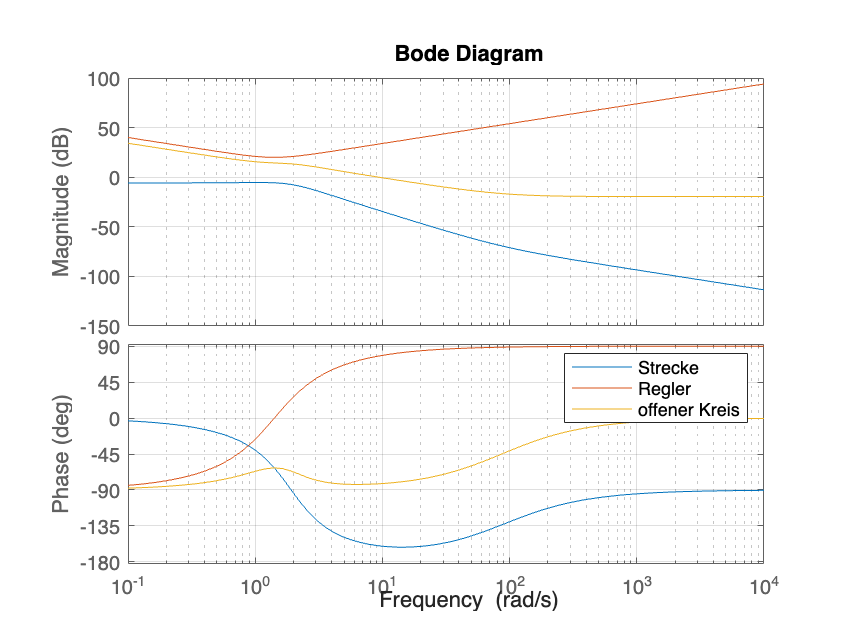

% Offener Kreis
GK0 = K*G0;

% Bode-Diagramme
bode(G0,K,GK0,{10^-1 10^4})
grid on
legend('Strecke','Regler','offener Kreis')

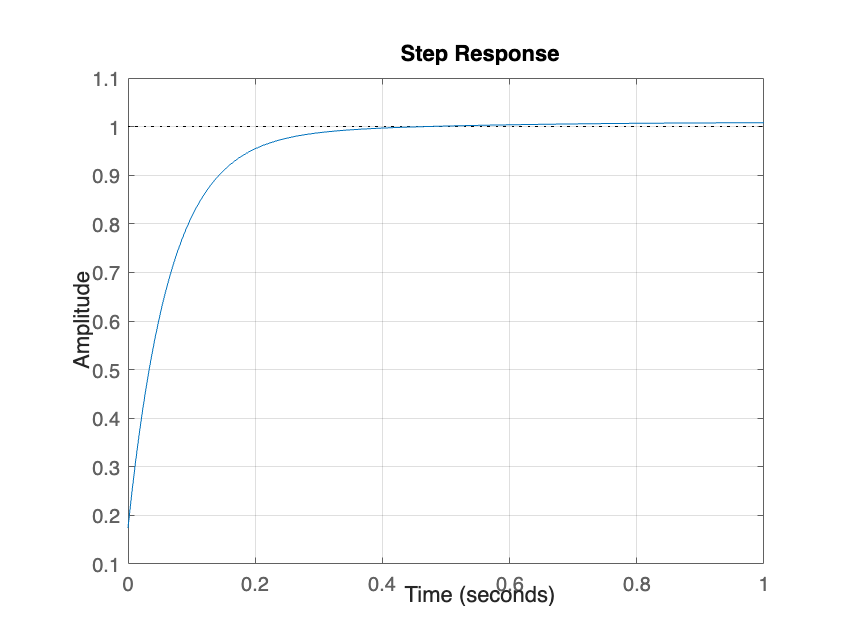


% Geschlossener Kreis
GRK = feedback(GK0,1); %GK0/(1 + GK0);

% Sprungantwort geschlossener Kreis
step(GRK,1)
grid on